# Team project: Incompressible potential flow around an airfoil

UE 322.061 Num1, SS 2021

created by:

Franz Haller, 01525883

Simon Klocker, 01526685

David Kerekes, 01226653

### 1.    Problem formulation

Cauchy-Riemann equations:

Irrotationality:

$\nabla \times \overrightarrow{u} \equiv \partial_x \;v-\partial_y \;u=0$      (1a)

Incompressibility:

$\nabla \cdot \overrightarrow{u} \equiv \partial_x \;u+\partial_y \;v=0$       (1b)

No-penetration boundary condition:


$$\overrightarrow{u} \cdot \overrightarrow{n} =0\;\;\;\;\;\;\;\;\;\textrm{on}\;\;\;\;\;\;\;\;\Gamma_C \cup \Gamma_F$$


                                                                                           (1c)


$$\;\Gamma_C \;:\sqrt{x^2 +y^2 }=r_c \;,\;\;\;\;\;\;\;\;\;\;\Gamma_F :y=0$$


Far-field condition:


$$\overrightarrow{u} \to \left(1,0\right)\;\;\;\;\;\;\;\textrm{as}\;\;\;\;\;\;\;x^2 +y^2 \to \infty$$


Approximating the far-field condition by imposing a Dirichlet BC on the outer boundary:

$\overrightarrow{u} \to \left(1,0\right)\;\;\;\;\;\;\;\textrm{at}\;\;\;\;\;\;\;\Gamma_O :\sqrt{x^2 +y^2 }=r_o$           (1d)

### 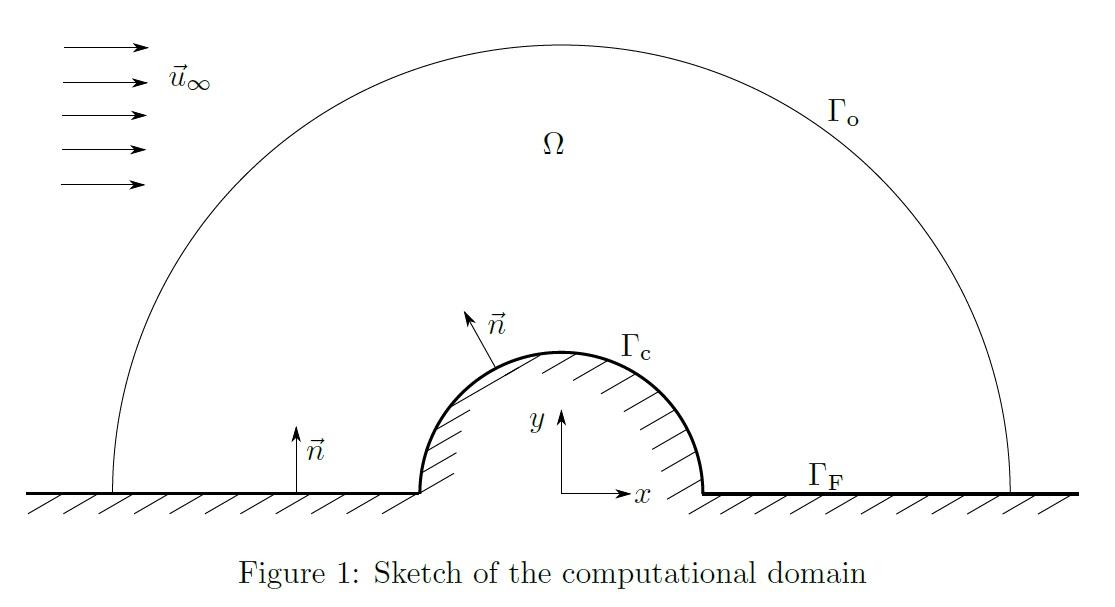

#### 1a) Determine the type of the system (1). Comment if and where we have to impose initial and boundary conditions.

To determine the type of a system of first order PDE´s we look at the general form in Matrix-vector notation:


$$\mathbf{A}\partial_{\mathrm{x}\;} \mathbf{u}+\mathbf{B}\partial_{\mathrm{y}} \;\mathbf{u}+\textrm{Cu}=0$$


Where we can define A, B and C:

clearvars;
close all;

syms dx dy u1 v1;
syms M real;

A = [0,1;
    1,0]

B = [-1,0;
    0,1]

C = [0,0;
    0,0]

Now we determine the type by solving:


$$\textrm{det}\left(A^T \textrm{dy}-B^T \textrm{dx}\right)=0$$


determinant = det(A'*dy-B'*dx)
solve(determinant == 0 , dx)

So we get no real solutions for the System. We conclude that the PDE-System is **elliptic.**

Since we have an elliptic equation, boundary conditions must be defined over all boundaries. There is no time-derivative so no initial conditions have to be made.

#### 1b)The velocity field satisfying (1) is potential, which means there exists a velocity potential $\phi$ such that

$\vec{u} =\nabla \phi$ (2)

#### Show that using (2) the system (1a,1b) reduces to and equivalent Laplace equation

$\nabla^2 \phi =0$ (3)

The irrotationality of $\overrightarrow{u} ={\left(u,v\right)}^T$ is defined as

$\nabla \times \overrightarrow{u} \equiv \partial_x v-\partial_y u=0$    (1a)

and the incompressibility as

$\nabla \cdot \overrightarrow{u} \equiv \partial_x u+\partial_y v=0$    (1b)

Using (2) in (1a) shows that the rotation is zero


$$\left\lbrack \begin{array}{c}
u\\
v
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\partial_x \;\phi \;\\
\partial_y \;\phi 
\end{array}\right\rbrack$$



$$\partial_x v-\partial_y u=\partial_{\textrm{xy}} \phi -\partial_{\textrm{xy}} \phi =0$$


By substitute (2) in (1b) we get the Laplace equation


$$\partial_x u+\partial_y v=\partial_{\textrm{xx}} \phi +\partial_{\textrm{yy}} \phi =0$$



$$\nabla^2 \phi =0$$


#### 1c) Confirm that the type of (3) is the same as the type of (1)

Rewriting (3):


$$\frac{\partial^2 \phi }{\partial x^2 }+\frac{\partial^2 \phi }{\partial y^2 }=0$$


Comparing with a general linear PDE:


$$\left(A\partial_x^2 +B\partial_{\textrm{xy}} +C\partial_y^2 \right)u\left(x,y\right)=0$$


and the factor


$$s=-\frac{B}{2A}\pm \frac{1}{2A}\sqrt{B^2 -4\textrm{AC}}$$



$$A=1,\;\;B=0,\;\;C=1$$


and

$s=0\pm \frac{1}{2}\sqrt{-4}=\pm \sqrt{-1}$,  a complex value.

The factors of the discriminate:


$$B^2 -4\textrm{AC}=-4\;\;\;<0\;\;\;\;$$


According to (1.24) of the script the type of (3) is **elliptic**, which is the same as of (1).

#### 1.d) Confirm that the boundary conditions

$\frac{\partial \phi }{\partial r}=0\;\;\textrm{at}\;\;\Gamma_C$        $\frac{\partial \phi }{\partial \theta }=0\;\;\textrm{at}\;\;\Gamma_F$        (4a)

$\phi =x\;\;\;\textrm{at}\;\;\Gamma_0$                                        (4b)

#### are equivalent to (1c,1d)

$\frac{\partial \phi }{\partial r}=0\;\;\textrm{at}\;\;\Gamma_C$:


$$x:\frac{\partial \phi }{\partial r}=\frac{\partial \phi }{\partial x}\frac{\partial x}{\partial r}=u\frac{\partial }{\partial r}r\;\cos \left(\theta \right)=u\;\cos \left(\theta \right)$$



$$y:\frac{\partial \phi }{\partial r}=\frac{\partial \phi }{\partial y}\frac{\partial y}{\partial r}=v\frac{\partial }{\partial r}r\;\sin \left(\theta \right)=v\;\;\sin \left(\theta \right)$$


This is equivalent to $\vec{u} \cdot \vec{n}$

$\frac{\partial \phi }{\partial \theta }=0\;\;\textrm{at}\;\;\Gamma_F$:


$$x:\frac{\partial \phi }{\partial \theta }=\frac{\partial \phi }{\partial x}\frac{\partial x}{\partial \theta }=u\frac{\partial }{\partial \theta }r\;\cos \left(\theta \right)=u\;r\;\left(-\sin \left(\theta \right)\right)$$



$$y:\frac{\partial \phi }{\partial \theta }=\frac{\partial \phi }{\partial y}\frac{\partial y}{\partial \theta }=v\frac{\partial }{\partial \theta }r\;\sin \left(\theta \right)=v\;\;r\;\cos \left(\theta \right)$$


This is equivalent to $\vec{u} \cdot \vec{n}$


$$\phi =x\;\;\;\textrm{at}\;\;\Gamma_0 :$$


means $\frac{\partial \phi }{\partial x}=\frac{\partial x}{\partial x}=1$

with $\vec{u} =\nabla \phi$

leads to $\vec{u} =u\left(1,0\right)$

### 2.    Transformation of coordinates

We can simplify the mesh generation and implementation of the no-penetration boundary condition by solving (1) in polar coordinates

$\theta =\arctan \left(\frac{y}{x}\right)$        $r=\sqrt{x^2 +y^2 }$        (5a)

$x=r\;\cos \;\theta$            $y=r\;\sin \;\theta$              (5b)

The transformed computational domain is then given by the rectangle $\Omega =\langle 0,\pi \rangle \times \langle r_c ,r_o \rangle$.

#### 2a)Find the Jacobian of the coordinate transformation

$\mathbf{J}=\left\lbrack \begin{array}{cc}
\frac{\partial x}{\partial \theta } & \frac{\partial y}{\partial \theta }\\
\frac{\partial x}{\partial r} & \frac{\partial y}{\partial r}
\end{array}\right\rbrack$ (6)

syms theta r
x=r*cos(theta);
y=r*sin(theta)
J=[diff(x,theta), diff(y,theta)
    diff(x,r), diff(y,r)]

#### 2.b) Express the inverse transformation of partial derivatives

$\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x}\\
\frac{\partial }{\partial y}
\end{array}\right\rbrack ={\mathbf{J}}^{-1} \left\lbrack \begin{array}{c}
\frac{\partial }{\partial \theta }\\
\frac{\partial }{\partial r}
\end{array}\right\rbrack$ (7)

J_theta_r=simplify(inv(J))

#### 2.c) Check that the inverse transformation (7) satisfies the chain rule

$\frac{\partial }{\partial x}=\frac{\partial \theta }{\partial x}\;\frac{\partial }{\partial \theta }+\frac{\partial r}{\partial x}\;\frac{\partial }{\partial r}$ (8a)

$\frac{\partial }{\partial y}=\frac{\partial \theta }{\partial y}\;\frac{\partial }{\partial \theta }+\frac{\partial r}{\partial y}\;\frac{\partial }{\partial r}$ (8b)

Calculated with (7):

d_dx_dy_1=[simplify(diff(J_theta_r(1,1),theta)+diff(J_theta_r(1,2),r))
    simplify(diff(J_theta_r(2,1),theta)+diff(J_theta_r(2,2),r))]

Calculated with the chain rule:

syms theta r x y
theta_1=atan(y/x);
r_1=sqrt(x^2+y^2);

a1=diff(theta_1,x);
a1=subs(a1,x,r*cos(theta));
a1=subs(a1,y,r*sin(theta));
a1=simplify(a1);
a2=diff(r_1,x);
a2=subs(a2,x,r*cos(theta));
a2=subs(a2,y,r*sin(theta));
a2=simplify(a2);

d_dx_2=diff(a1,theta)+diff(a2,r);

b1=diff(theta_1,y);
b1=subs(b1,x,r*cos(theta));
b1=subs(b1,y,r*sin(theta));
b1=simplify(b1);
b2=diff(r_1,y);
b2=subs(b2,x,r*cos(theta));
b2=subs(b2,y,r*sin(theta));
b2=simplify(b2);

d_dy_2=diff(b1,theta)+diff(b2,r);
d_dx_dy_2=[simplify(diff(a1,theta)+diff(a2,r))
   simplify(diff(b1,theta)+diff(b2,r))]

The results are the same:


$$\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x}\\
\frac{\partial }{\partial y}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{\cos \left(\theta \right)}{r}\\
-\frac{\sin \left(\theta \right)}{r}
\end{array}\right\rbrack$$


#### 2.d) Find the expressions to compute the Cartesian second partial derivatives $\frac{\partial }{\partial x}\left(\frac{\partial }{\partial x}\right)$and $\frac{\partial }{\partial y}\left(\frac{\partial }{\partial y}\right)$ from the polar partial derivatives $\frac{\partial^2 }{\partial \theta^2 }$, $\frac{\partial^2 }{\partial r^2 }$, $\frac{\partial^2 }{\partial \theta \partial r}$, $\frac{\partial }{\partial \theta }$, $\frac{\partial }{\partial r}$:


$$\frac{\partial }{\partial x}\left(\frac{\partial }{\partial x}\right)=\frac{\partial^2 \theta }{\partial x^2 }\;\frac{\partial^2 }{\partial \theta^2 }+2\;\frac{\partial \theta }{\partial x}\frac{\partial r}{\partial x}\frac{\partial^2 }{\partial \theta \partial r}+\frac{\partial^2 r}{\partial x^2 }\frac{\partial^2 }{\partial r^2 }$$



$$\frac{\partial }{\partial y}\left(\frac{\partial }{\partial y}\right)=\frac{\partial^2 \theta }{\partial y^2 }\;\frac{\partial^2 }{\partial \theta^2 }+2\;\frac{\partial \theta }{\partial y}\frac{\partial r}{\partial y}\frac{\partial^2 }{\partial \theta \partial r}+\frac{\partial^2 r}{\partial y^2 }\frac{\partial^2 }{\partial r^2 }$$


#### 2e) Let us introduce a position vector 

$\overrightarrow{x} :=x{\overrightarrow{e} }_x +y{\overrightarrow{e} }_y \equiv r\;\cos \theta {\overrightarrow{e} }_x +r\;\sin \theta {\overrightarrow{e} }_y$    (9)

#### in cartesian coordinates. Express the polar basis vectors.

${\overrightarrow{e} }_r =\frac{\partial \overrightarrow{x} }{\partial r}/{\left\|\frac{\partial \overrightarrow{x} }{\partial r}\right\|}_2$  ,  ${\overrightarrow{e} }_{\theta } =\frac{\partial \overrightarrow{x} }{\partial \theta }/{\left\|\frac{\partial \overrightarrow{x} }{\partial \theta }\right\|}_2$    (10)

#### in terms of the Cartesian ones.


$$\overrightarrow{x} =\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r\;\cos \left(\theta \right)\\
r\;\sin \left(\theta \right)
\end{array}\right\rbrack$$


clear all
syms r theta x F_x F_y delta_x delta_y e_x e_y;

%x = r*cos(theta);
%y = r*sin(theta);
x_vec = [r*cos(theta),r*sin(theta)];

e_r = diff(x_vec,r)/norm(diff(x_vec,r))

e_theta = diff(x_vec,theta)/norm(diff(x_vec,theta))
%x = r*cos(theta);
%y = r*sin(theta);

and so we get:


$${\overrightarrow{e} }_r =\cos \left(\theta \right)\;{\overrightarrow{e} }_x +\sin \left(\theta \right)\;{\overrightarrow{e} }_y$$
 

 
$${\overrightarrow{e} }_{\theta } =-\sin \left(\theta \right)\;{\overrightarrow{e} }_x +\cos \left(\theta \right)\;{\overrightarrow{e} }_y$$


#### 2f) Invert the system (10) and express ${\overrightarrow{e} }_x$ and ${\overrightarrow{e} }_y$ in terms of  ${\overrightarrow{e} }_r$ and ${\overrightarrow{e} }_{\theta }$

For this task, we define a Transformation-Matrix T:

T = [cos(theta)  sin(theta)
    -sin(theta) cos(theta)]

inverting the System we get:

simplify(inv(T))

Therefore for ${\overrightarrow{e} }_x$ and ${\overrightarrow{e} }_y$:


$${\overrightarrow{e} }_x =\cos \left(\theta \right)\;{\overrightarrow{e} }_r -\sin \left(\theta \right)\;{\overrightarrow{e} }_{\theta }$$
 


$${\overrightarrow{e} }_y =\sin \left(\theta \right)\;{\overrightarrow{e} }_r +\cos \left(\theta \right)\;{\overrightarrow{e} }_{\theta }$$


#### 2g) Using the result of the previous question, show that the transformation of vectors from Cartesian to Polar basis reads:

$\overrightarrow{F} ={\mathrm{F}}_x \;\;{\overrightarrow{e} }_x +{\mathrm{F}}_x \;\;{\overrightarrow{e} }_y =\left({\mathrm{F}}_x \;\cos \left(\theta \right)+{\mathrm{F}}_y \;\sin \left(\theta \right)\right){\overrightarrow{e} }_r +\left({-\mathrm{F}}_x \;\sin \left(\theta \right)+{\mathrm{F}}_y \;\cos \left(\theta \right)\right){\overrightarrow{e} }_{\theta }$        (11)

To achieve that, we can Multiply the F-Vector with our Transformation-Matrix:

F_cart = [F_x; F_y];
F_pol = T * F_cart

so we get:


$$\overrightarrow{F} =\left({\mathrm{F}}_x \;\cos \left(\theta \right)+{\mathrm{F}}_y \;\sin \left(\theta \right)\right){\overrightarrow{e} }_r +\left({-\mathrm{F}}_x \;\sin \left(\theta \right)+{\mathrm{F}}_y \;\cos \left(\theta \right)\right){\overrightarrow{e} }_{\theta }$$


#### 2h) Using the results of the previous questions, show that the gradient in polar coordinates reads:

$\nabla ={\overrightarrow{e} }_r \partial_r +{\overrightarrow{e} }_{\theta } \frac{1}{r}\partial_{\theta }$          (12)

The Matrix  with the partial differentials for x and y (Jacobi Matrix) reads:

J = [diff(x_vec(1),r) diff(x_vec(1),theta)
    diff(x_vec(2),r) diff(x_vec(2),theta)]
e_cart = [e_x; e_y]
grad_pol = simplify(J^-1*e_cart)

so we see with 2e)


$${\overrightarrow{e} }_r =\cos \left(\theta \right)\;{\overrightarrow{e} }_x +\sin \left(\theta \right)\;{\overrightarrow{e} }_y$$
 

 
$${\overrightarrow{e} }_{\theta } =-\sin \left(\theta \right)\;{\overrightarrow{e} }_x +\cos \left(\theta \right)\;{\overrightarrow{e} }_y$$


that the gradient in polar coordinates reads:


$$\nabla ={\overrightarrow{e} }_r \partial_r +{\overrightarrow{e} }_{\theta } \frac{1}{r}\partial_{\theta }$$


#### 2i) **Show that Laplace operator in polar coordinates reads **

$\nabla^2 \equiv \frac{1}{r}\frac{\partial }{\partial r}+\frac{\partial^2 }{\partial r^2 }+\frac{1}{r^2 }\frac{\partial^2 }{\partial \theta^2 }$       (13)

Let $f\left(x,y\right)$ be a function depending on $x\;,y\;$, then the Laplace operation gives us


$$\nabla^{2\;} f\left(x,y\right)=\frac{\partial^2 }{\partial x^2 }f\left(x,y\right)+\frac{\partial^2 }{\partial y^2 }f\left(x,y\right)$$


The coordinate transformation from cartesian system $\left(x,y\right)$in polar system$\left(r,\theta \right)$ and backwards are defined as follows,


$$x=r\cdot \cos \left(\theta \right)$$



$$y=r\cdot \sin \left(\theta \right)$$



$$r=\sqrt{x^2 +y^2 }$$



$$\theta =\arctan \left(\frac{y}{x}\right)$$



$$f\left(x\left(r,\theta \right),y\left(r,\theta \right)\right)\equiv u\left(r\left(x,y\right),\theta \left(x,y\right)\right)$$


Using the chain rule, the derivatives with respect to x are


$$u_x =u_r \cdot r_x +u_{\theta } \cdot \theta_x \;\;$$



$$u_{\textrm{xx}} =\left(u_{\textrm{rr}} \cdot r_x +u_{r\theta } \cdot \theta_x \right)\cdot r_x +u_r \cdot r_{\textrm{xx}} +\left(u_{\theta r} \cdot r_x +u_{\theta \theta } \cdot \theta_x \right)\cdot \theta_x +u_{\theta } \cdot \theta_{\textrm{xx}\;}$$



$$u_{\textrm{xx}} =u_{\textrm{rr}} \cdot {r_x }^2 +2\cdot u_{r\theta } \cdot r_x \cdot \theta_x +u_{\theta \theta } \cdot {\theta_x }^2 +u_r \cdot r_{\textrm{xx}} +u_{\theta } \cdot \theta_{\textrm{xx}}$$


Analogous the second derivative with respect to y is


$$u_{\textrm{yy}} =\left(u_{\textrm{rr}} \cdot r_y +u_{r\theta } \cdot \theta_y \right)\cdot r_y +u_r \cdot r_{\textrm{yy}} +\left(u_{\theta r} \cdot r_y +u_{\theta \theta } \cdot \theta_y \right)\cdot \theta_y +u_{\theta } \cdot \theta_{\textrm{yy}\;}$$



$$u_{\textrm{yy}} =u_{\textrm{rr}} \cdot {r_y }^2 +2\cdot u_{r\theta } \cdot r_y \cdot \theta_y +u_{\theta \theta } \cdot {\theta_y }^2 +u_r \cdot r_{\textrm{yy}} +u_{\theta } \cdot \theta_{\textrm{yy}}$$


Therefore our Laplace operation reads,


$$\nabla^2 \;u=\;u_{\textrm{xx}} +u_{\textrm{yy}} =u_{\textrm{rr}} \left({r_x }^2 +{r_y }^2 \right)+2\cdot u_{r\theta } \left(r_x \cdot \theta_x +r_y \cdot \theta_y \right)+u_{\theta \theta } \cdot \left({\theta_x }^2 +{\theta_y }^2 \right)+u_r \cdot \left(r_{\textrm{xx}} +r_{\textrm{yy}} \right)+u_{\theta } \cdot \left(\theta_{\textrm{xx}} +\theta_{\textrm{yy}} \right)$$


by inserting the following derivatives, 


$$r_x =\frac{x}{\sqrt{x^2 +y^2 }}=\frac{x}{r}$$



$$r_{\textrm{xx}} =\frac{r-x\cdot r_x }{r^2 }=\frac{r-x\cdot \frac{x}{r}}{r^2 }=\frac{r^2 -x^2 }{r^3 }=\frac{y^2 }{r^3 }$$



$$\theta_x =\frac{1}{1+{\left(\frac{y}{x}\right)}^2 }\cdot \left(-\frac{y}{x^2 }\right)=-\frac{y}{x^2 +y^2 }=-\frac{y}{r^2 }$$



$$\theta_{\textrm{xx}} =-\frac{0\cdot r^2 -2\cdot r\cdot r_x \cdot y}{r^4 }=\frac{2\cdot x\cdot y}{r^4 }$$



$$r_y =\frac{y}{r}$$



$$r_{\textrm{yy}} =\frac{x^2 }{r^3 }$$



$$\theta_y =\frac{1}{1+{\left(\frac{y}{x}\right)}^2 }\cdot \left(\frac{1}{x}\right)=\frac{x}{r^2 }$$



$$\theta_{\textrm{yy}} =\frac{0\cdot r^2 -2\cdot r\cdot r_y \cdot x}{r^4 }=-\frac{2\cdot x\cdot y}{r^4 }$$


we get, 


$${\nabla^2 =u}_{\textrm{xx}} +u_{\textrm{yy}} =u_{\textrm{rr}} \left({\left(\frac{x}{r}\right)}^2 +{\left(\frac{y}{r}\right)}^2 \right)+2\cdot u_{r\theta } \left(\frac{x}{r}\cdot -\frac{y}{r^2 }+\frac{y}{r}\cdot \frac{x}{r^2 }\right)+u_{\theta \theta } \cdot \left({\left(-\frac{y}{r^2 }\right)}^2 +{\left(-\frac{x}{r^2 }\right)}^2 \right)+u_r \cdot \left(\frac{y^2 }{r^3 }+\frac{x^2 }{r^3 }\right)+u_{\theta } \cdot \left(\frac{2\cdot x\cdot y}{r^4 }-\frac{2\cdot x\cdot y}{r^4 }\right)$$



$$\;\;\;\nabla^2 \;u=u_{\textrm{rr}} +u_{\theta \theta } \cdot \frac{1}{r^2 }+u_r \cdot \frac{1}{r}$$


#### 2j) **Write a MATLAB function [u_c,v_c,x,y] = VecPol2Cart(u_p,v_p,theta,r) to convert a discrete polar vector field to Cartesian coordinates.**

The coordinate transformation from polar system to cartesian system is given by


$$\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r\;\cos \left(\;\theta \;\right)\\
r\;\sin \left(\theta \right)
\end{array}\right\rbrack$$


To convert a vector we can use the following transformation matrix 


$$\left\lbrack \begin{array}{c}
u_c \\
v_c 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\\
\sin \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
u_p \\
v_p 
\end{array}\right\rbrack$$


By combining these two transformations we can convert a discrete polar vector field to cartesian coordinates. The following function was given in the template folder.

function [uc,vc,x,y] = VecPol2Cart(up,vp,theta,r)
%VECPOL2CART Transform polar vector to Cartesian
%   Transform vector from polar basis to Cartesian basis
[x,y] = pol2cart(theta,r);
uc = up.*cos(theta) -vp.*sin(theta);
vc = up.*sin(theta) +vp.*cos(theta);
end

### 3.    Discretization

Let us discretize (3) on a two-dimensional polar grid with *I* and *J* number of points in r and $\theta$ direction respectively, such that $\phi_{i,j} =\phi \left(\theta_{i,j} ,r_{i,j} \right)$.

The coordinates of the grid points are given by


$$\theta_‾ =\left\lbrack \begin{array}{ccc}
0 & \cdots  & \pi \\
\vdots  &  & \vdots \\
0 & \cdots  & \pi 
\end{array}\right\rbrack \;\;\;,\;\;\;\underline{r} =\left\lbrack \begin{array}{ccc}
r_c  & \cdots  & r_c \\
\vdots  &  & \vdots \\
r_0  & \cdots  & r_0 
\end{array}\right\rbrack$$


We will approximate partial derivatives with the standard second-order centered definite differences

$\frac{\partial \phi }{\partial \theta }|_{i,j} \approx \frac{\phi_{i,j+1} -\phi_{i,j-1} }{2\Delta \theta }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\partial \phi }{\partial r}|_{i,j} \approx \frac{\phi_{i+1,j} -\phi_{i-1,j} }{2\Delta r}$         (14a) 

$\frac{\partial^2 \phi }{\partial \theta^2 }|_{i,j} \approx \frac{\phi_{i,j-1} -2\phi_{i,j} +\phi_{i,j+1} }{\Delta \theta^2 }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\partial^2 \phi }{\partial r^2 }|_{i,j} \approx \frac{\phi_{i-1,j} -2\phi_{i,j} +\phi_{i+1,j} }{\Delta r^2 }$       (14b)

#### 3.a) Provide a MATLAB code `[r,theta,dr,dtheta]` `= GenerateMesh(rc,ro,I,J)` to generate the matrices of grid point coordinates $\;\underline{r} ,\theta_‾$ and the grid spacings $\Delta r,\Delta \theta$.

function [r,theta,dr,dtheta] = GenerateMesh(rc,ro,I,J)
%GENERATEMESH in polar coordinates and return grid spacings
%   Generates polar coordinates of uniformly distributed grid points

% IMPLEMENT YOUR CODE HERE

%calculate dr
dr = (ro-rc)/(I-1);
%calculate dhteta
dtheta = pi/(J-1);

r= meshgrid(rc:dr:ro,1:J)';
theta = meshgrid(0:dtheta:pi,1:I);
end

#### 3b)Provide a MATLAB code `[ii,io,il,ir] = BoundaryIndices(r,theta)` to find the indices $i_i ,i_o ,i_l$ and $i_r$ of grid points belonging to the boundaries $r=r_c ,r=r_o ,\theta =0$ and $\theta =\pi$.

function [ii,io,il,ir,rc,ro,thl,thr] = BoundaryIndices(r,theta)
%BOUNDARYINDICES Find indices of boundary points
%   Finds indices of grid points belonging to different boundaries
%   
rc = r(1);
ro = r(end);
thl = theta(1);
thr = theta(end);

% TODO: FIND ii,io,il and ir 
ii = find(r(:)==rc);
io = find(r(:)==ro);
il = find(theta(:)==thl);
ir = find(theta(:)==thr);
end


#### 3c) As usual, we will flatten $\phi_{i,j}$ into a column vector $\phi_m$ where $m=i+\left(1-j\right)I$ enumerates all the grid points. Re-write (14) using the linear indexing $m$ and produce a MATLAB code `[Dr,Dth,Dr2,Dth2] = PartialDerivatives(r,th)` to create the matrices for discretization of partial derivatives with the second-order centered finite-differences.

function [Dr,Dth,Dr2,Dth2] = PartialDerivatives(r,theta)
%PARTIALDERIVATIVES Returns finite-difference discretization matrices
%   Generates sparse matrix representation of the finite-difference
%   approximation of the partial derivatives in polar coordinates

[I,J] = size(r);
m = I*J;
e = ones(m,1);
dr = r(2,1) - r(1,1);
dth= theta(1,2) - theta(1,1);

% TODO
Dr = spdiags([-1*e/(2*dr) 1*e/(2*dr)],[-1 1],m,m);
Dr2 = spdiags( [ 1*e/dr^2 -2*e/dr^2 1*e/dr^2 ] , [ -1  0  1 ] , m,m );

Dth = spdiags([-1*e/(2*dth) 1*e/(2*dth)],[-I I],m,m);
Dth2 = spdiags( [ 1*e/dth^2 -2*e/dth^2 1*e/dth^2 ] , [ -I  0  I ] , m,m );
end

#### 3d) Write a MATLAB function `A = PolarLaplacian(r,Dr,Dr2,Dth2)` to compute the discretization matrix for the Laplace operator in polar coordinates

function [A] = PolarLaplacian(r,Dr,Dr2,Dth2)
%POLARLAPLACIAN Finite-difference approximation of Laplacian in polar coor.
%   Generates sparse matrix representation of the finite-difference
%   approximation of the Laplace operator in polar coordinates

% TODO
A = r(:).^-1.*Dr + Dr2 + r(:).^-2.*Dth2;
end

#### 3e) Write a MATLAB function `[A,b] = DirichletBC(A,b,alpha,iD)` to impose a non-uniform Dirichlet

#### boundary condition `phi(iD)=alpha` in a given linear system


$$\underline{A} \phi^{\to } =\overrightarrow{b}$$


#### at the grid points with indices `iD`. The suggested inputs are:

- `A` - the matrix $\underline{A}$ corresponding to the finite-difference approximation of the homogeneous part of the PDE to be solved.

-  `b` - the vector of the discrete right-hand side $\overrightarrow{b}$ of the PDE to be solved (zero vector for a homogeneous PDE).

- `alpha` - vector of the Dirichlet values corresponding to the indices `iD`

- `iD` - indices of those grid points where the Dirichlet BC is to be imposed

function [A,b] = DirichletBC(A,b,alpha,iD)
%DIRICHLETBC Impose phi(iD)=alpha
%   Impose Dirichlet boundary condition phi=alpha in a given system A*phi=b
%   at the boundary points whose indices are in iD

N = numel(b);
I = speye(N);


% TODO
%!!!!!!!!!!!!!!!! check I or 0 !!!!!!!!!!!!!!!
A(iD,:)=I(iD,:);



for i=1:length(iD)
    b(i*length(iD)) = alpha(i);
end

end

#### 3f) Write a MATLAB `function [A,b] = NeumannBC(A,b,beta,iN,dn,ig)` to impose a Neumann boundary condition

$\frac{\partial \phi }{\partial n}=\beta$,            where  $\frac{\partial }{\partial n}=n_r \;\partial_r +n_{\theta } \;\partial_{\theta }$,

at the boundary grid points with indices `iN`. Use the ghost-point method

$\frac{\phi_{m+\textrm{ig}} -\phi_{m-\textrm{ig}} }{\textrm{dn}}=\beta$,        where $\textrm{dn}=n_r \Delta r+n_{\theta } \Delta \theta$

and `ig` is the (theoretical) index of the ghost points relative to the boundary points `iN`.

Hint: Don't forget to erase those entries of $\underline{A}$ which correspond to the opposite boundary.

function [A,b] = NeumannBC(A,b,beta,iN,dn,iG)
%NEUMANNBC Impose Neumann BC at grid points iN
%   Impose Neumann BC at boundary grid points with indices in iN

for i = iN'

    % TODO: IMPLEMENT NEUMANN BC
    
    % !!!!!!! vorzeichen iG überprüfen !!!!!!!
    
  
    A(i,i-iG) = A(i,i-iG)+A(i-iG,i);
    b(i)=b(i)+ 2*A(i-iG,i)*dn*beta;
  
    if i+iG>0 && i+iG<size(A,2)
        % TODO: ERASE LINK TO THE OPPOSITE BOUNDARY
        % size(A,2) ... number of columns
        A(i,i+iG)=0;
    end
    
end

end

### 4.    Computation of the velocity field

#### 4a) Compute the velocity potential $\phi$ for rc = 0:5; ro = 3; I = J = 31 using the template function

#### [phi,x,y] = ComputePotential(rc,ro,I,J). Compare the contours of $\phi$ to the analytical solution $\phi_a$ returned by `phi_a = AnalyticalPotential(rc,x,y)`.

function [phi,x,y,r,th,Dr,Dth] = ComputePotential(rc,ro,I,J)
%COMPUTEPOTENTIAL Compute velocity potential
%   of an incompressible irrotational flow around a cylinder in polar
%   coordinates

[r,th,dr,dth] = GenerateMesh(rc,ro,I,J);
[x,y] = pol2cart(th,r);

[Dr,Dth,Dr2,Dth2] = PartialDerivatives(r,th);
[A] = PolarLaplacian(r,Dr,Dr2,Dth2);
b = sparse(I*J,1);

[ii,io,il,ir] = BoundaryIndices(r,th);

[A,b] =   NeumannBC(A,b,0,ii,dr ,-1);
[A,b] =   NeumannBC(A,b,0,il,dth,-I);
[A,b] =   NeumannBC(A,b,0,ir,dth, I);
[A,b] = DirichletBC(A,b,x(io),io);

phi = reshape( A\b ,I,J);

end

#### 4b)The centered finite-difference matrices for first derivatives `Dr` and `Dth` are not valid on some boundaries. Write a MATLAB function `[Dr,Dth] = BoundaryDerivatives(r,th,Dr,Dth)` to modify `Dr` and `Dth` such that on those boundaries where the derivatives cannot be computed with centered finite differences they will be computed with first-order one-sided finite differences. The rows corresponding to interior grid points should remain unaffected.

function [Dr,Dth] = BoundaryDerivatives(r,th,Dr,Dth)
%BOUNDARYDERIVATIVES Corrects the finite-difference matrices on boundaries
%   Replaces centered finite difference with one-sided finite difference
%   where necessary
%   

[I,J] = size(r);
N = I*J;
e = ones(N,1);
dr = r(2,1) - r(1,1);
dth= th(1,2) - th(1,1);
[ii,io,il,ir] = BoundaryIndices(r,th);

% TODO: CREATE DISCRETIZATION MATRICES WITH ONE-SIDED FINITE DIFFERENCES
Dr_fw = spdiags([-1*e/dr 1*e/dr],[0 1],N,N);
Dth_fw = spdiags([-1*e/dth 1*e/dth],[0 I],N,N);

Dr_bw = spdiags([-1*e/dr 1*e/dr],[-1 0],N,N);
Dth_bw = spdiags([-1*e/dth 1*e/dth],[-I 0],N,N);

% TODO: REPLACE THE ROWS OF Dr AND Dth CORRESPONDING TO THE PROBLEMATIC
% BOUNDARIES WITH THE MATCHING ROWS OF THE ONE-SIDED MATRICES
Dr(ii,:)=Dr_fw(ii,:);
Dr(io,:)=Dr_bw(io,:);
Dth(il,:)=Dth_fw(il,:);
Dth(ir,:)=Dth_bw(ir,:);
end

#### 4c)Write a MATLAB function `[uc,vc,up,vp] = ComputeVelocity(phi,r,th)` to compute the polar velocity components from the velocity potential


$$\left\lbrack \begin{array}{c}
u_p \\
v_p 
\end{array}\right\rbrack =\nabla \phi \equiv \left\lbrack \begin{array}{c}
\partial_r \\
\frac{1}{r}\partial_{\theta } 
\end{array}\right\rbrack \phi$$


#### and convert them to Cartesian velocity components using `VecPol2Cart`. Compare the Cartesian velocity field to the analytical solution returned by `[ua,va] = AnalyticalVelocity(rc,x,y)`. Plot both vector fields using `quiver`.

Hint: Use the matrices Dr and Dth.

function [uc,vc,up,vp] = ComputeVelocity(phi,r,th)
%COMPUTEVELOCITY Compute velocity of the potential flow
%   around a cylinder in polar coordinates

[I,J] = size(r);
[Dr,Dth] = PartialDerivatives(r,th);
[Dr,Dth] = BoundaryDerivatives(r,th,Dr,Dth);
% TODO: COMPUTE THE POLAR VELOCITY COMPONENTS up AND vp

up = Dr*phi(:);
vp = r(:).^-1.*Dth*phi(:);

up = full(reshape(up,I,J));
vp = full(reshape(vp,I,J));

[uc,vc] = VecPol2Cart(up,vp,th,r);
end

function [uc,vc,x,y] = VecPol2Cart(up,vp,theta,r)
%VECPOL2CART Transform polar vector to Cartesian
%   Transform vector from polar basis to Cartesian basis
[x,y] = pol2cart(theta,r);
uc = up.*cos(theta) -vp.*sin(theta);
vc = up.*sin(theta) +vp.*cos(theta);
end

function [u,v] = AnalyticalVelocity(ri,x,y)
%ANALYTICALVELOCITY of the potential flow around a cylinder
%   Returns the two-dimensional velocity field of the potential flow around
%   a circular cylinder using an analytical formula.

z = x + 1i*y;
U = 1-ri^2./z.^2;
u =  real(U);
v = -imag(U);

end

### 5.    Pressure force

#### 5a) Write a MATLAB function `[p] = ComputePressure(u,v)` to compute the pressure field from the velocity components, using the Bernouli equation

$p=\frac{1}{2}-\frac{1}{2}\sqrt{u^2 +v^2 }$                (15)

Note: The reference pressure $p_0 =\frac{1}{2}$ can be selected arbitrarily. The value selected here is such that the far field static pressure $p_{\infty } =0$.

function [p] = ComputePressure(u,v)
%COMPUTEPRESSURE of a potential flow from a given velocity field
%   Computes dynamic pressure of a potential flow using the Bernouli
%   equation

[I,J] = size(u);

% TODO: COMPUTE PRESSURE FROM THE VELOCITY COMPONENTS
e = ones(I*J,1);


p = e.*1/2 - 1/2*(u(:).^2+v(:).^2);

p = reshape(p,I,J);

end

#### 5b) Plot the contours of the pressure field.

#### 5c) Write a function `[Fx,Fy] = ComputeForce(p,r,th)` to integrate the pressure along the surface of the half-cylindrical bump in order to obtain the total pressure force acting on the bump per unit spanwise

#### length

Use any numerical integration scheme that you want (e.g. left Riemann sum, right Riemann sum, midpoint rule or trapezoidal rule).

#### 5d) Is the total pressure force in agreement with the theory of potential flows? Explain.

### 6.    Streamlines

Streamlines of a steady flow are in polar coordinates governed by

                                                                           $\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
\theta \\
r
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u\left(\theta ,r\right)\\
v\left(\theta ,r\right)/r
\end{array}\right\rbrack$                                           (17)

We want to compute a set of streamlines initiated from a set of $N$ seeding points$\left\lbrack \theta_1 ,r_1 \right\rbrack ,\ldotp \ldotp \ldotp ,\left\lbrack \theta_N ,r_N \right\rbrack$. Thus we have to integrate an explicit system of $2N$ first-order ODEs.

Although several ODE solvers are available in MATLAB, we are so badass that we will implement our own version of the Dormand-Prince algorithm RK5(4)7M (Dormand and Prince, 1980, Table 2) known as `ode45`. It is an adaptive time step algorithm based on the 5th order Runge-Kutta method with the Butcher tableau given in Table 1. Recall that a general Butcher tabelau as in Table 2 defines the Runge-Kutta method for ${\overrightarrow{y} }^{\prime } =\overrightarrow{f} \left(t,\overrightarrow{y} \right)$ as


$${\overrightarrow{k} }_1 =\overrightarrow{f} \left(t_n ,{\overrightarrow{y} }_n \right)$$



$${\overrightarrow{k} }_2 =\overrightarrow{f} \left(t_n +a_2 \Delta t,{\overrightarrow{y} }_n +\Delta t\left(b_{11} {\overrightarrow{k} }_1 \right)\right)$$


                                                                                        $\vdots$                                                                (18)


$${\overrightarrow{k} }_s =\overrightarrow{f} \left(t_n +a_s \Delta t,{\overrightarrow{y} }_n +\Delta t\left(b_{s-1,1} {\overrightarrow{k} }_1 +\cdots +b_{s-1,s-1} {\overrightarrow{k} }_{s-1} \right)\right)$$



$${\overrightarrow{y} }_{n+1} ={\overrightarrow{y} }_n +\Delta t\sum_{i=1}^s c_i {\overrightarrow{k} }_i$$


The advantage of the Dormand-Prince pairs is that a one order lower result can be obtained just by changing the coefficients $c_i$ without any additional evaluations of the function $\overrightarrow{f}$

                                                                         ${\hat{\overrightarrow{y} } }_{n+1} ={\overrightarrow{y} }_n +\Delta t\sum_{i=1}^{s-1} {\hat{c} }_i {\overrightarrow{k} }_i$                                       (19)

The difference between the lower and higher order result is a good and yet computationally cheap estimate of the discretization error at each time step. This estimate is used by `ode45` to adjust the time-step length $\Delta t$ such that the discretization error is of the same order of magnitude at all steps. The difference can also be expressed directly without explicitly computing the lower order result

                                                                ${\overrightarrow{y} }_{n+1} -{\hat{\overrightarrow{y} } }_{n+1} =\sum_{i=1}^s e_i {\overrightarrow{k} }_i$                 (20)

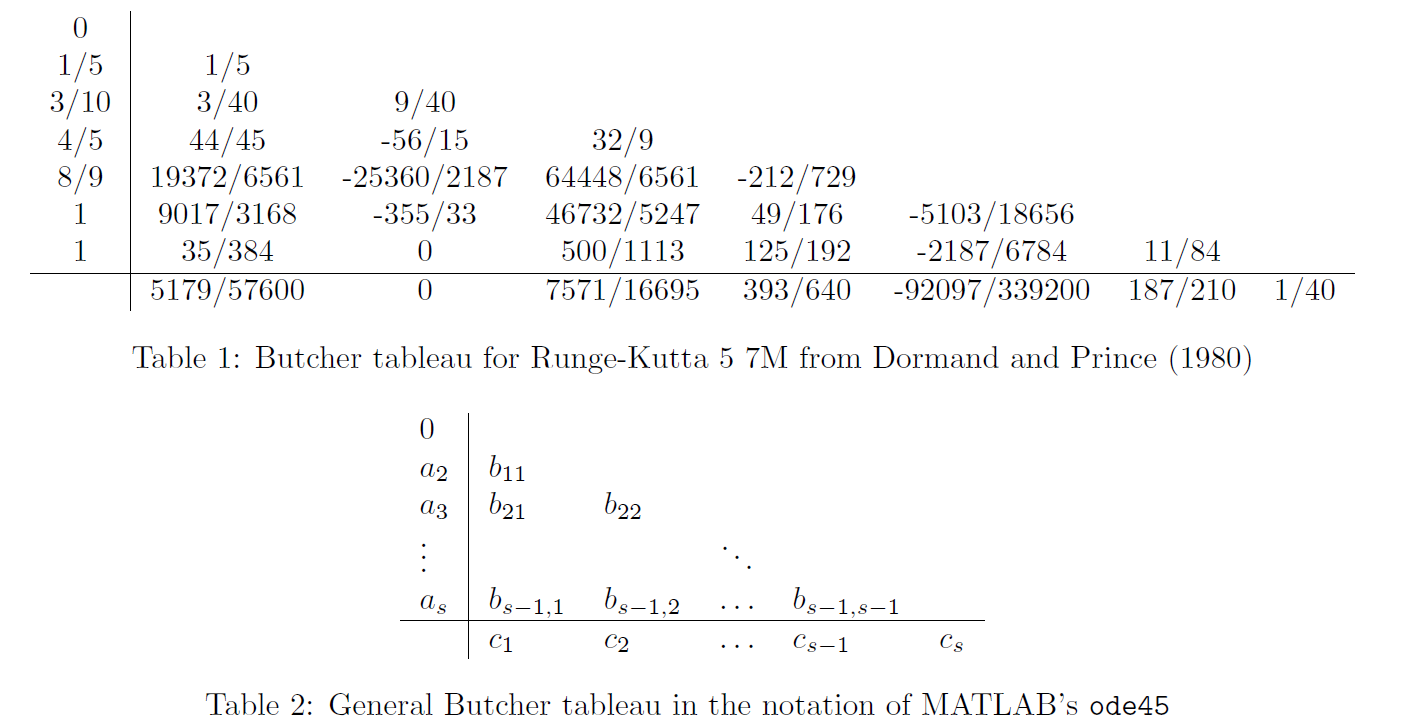

The coefficients ${\hat{c} }_i$ and $e_i$ for RK5(4)7M are given in Table 3.

The standard ODE solvers are designed for general systems of the form

 $\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_1 \left(t,y_1 ,y_2 ,\cdots ,y_N \right)\\
f_2 \left(t,y_1 ,y_2 ,\cdots ,y_N \right)\\
\vdots \\
f_N \left(t,y_1 ,y_2 ,\cdots ,y_N \right)
\end{array}\right\rbrack$                                           (21)

We will be a bit more specific and write a solver aimed at computation of multiple trajectories in a steady vector field

                                            $\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
r_1 \\
\theta_1 \\
\vdots \\
r_N \\
\theta_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_1 \left(t,y_1 ,y_2 ,\cdots ,y_N \right)\\
f_2 \left(t,y_1 ,y_2 ,\cdots ,y_N \right)\\
\vdots \\
f_N \left(t,y_1 ,y_2 ,\cdots ,y_N \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f_u \left(\theta_1 ,r_1 \right)\\
f_v \left(\theta_1 ,r_1 \right)\\
\vdots \\
f_u \left(\theta_N ,r_N \right)\\
f_v \left(\theta_N ,r_N \right)
\end{array}\right\rbrack$                                          (22)

where for polar coordinates we have $f_u =u,\;\;\;f_v =v/r$ fu = u, fv = v=r. We therefore want to construct the Runge-Kutta method as


$${\overrightarrow{k} }_{1r} =\overrightarrow{f_u } \left(\theta ,r\right)$$



$${\overrightarrow{k} }_{1\theta } =\overrightarrow{f_v } \left(\theta ,r\right)$$


                                                                                           $\vdots$                                                                (23)


$${\overrightarrow{k} }_{s\theta } =\overrightarrow{f_v } \left(\theta +\Delta t\sum_{i=1}^{s-1} b_{s-1,i} {\overrightarrow{k} }_{i\theta } \;\;,\;\;r+\Delta t\sum_{i=1}^{s-1} b_{s-1,i} {\overrightarrow{k} }_{\textrm{ir}} \right)$$



$${\overrightarrow{r} }_{n+1} ={\overrightarrow{r} }_n +\Delta t\sum_{i=1}^s c_i {\overrightarrow{k} }_{\textrm{ir}}$$



$${\theta^{\to } }_{n+1} ={\theta^{\to } }_n +\Delta t\sum_{i=1}^s c_i {\overrightarrow{k} }_{i\theta }$$


#### 6a) Implement the 5th order 7M Runge-Kutta method in the template function `[R,TH] = myode45(fu,fv,r0,th0)`. Note that the cofficients from the Butcher tableau are already defined:

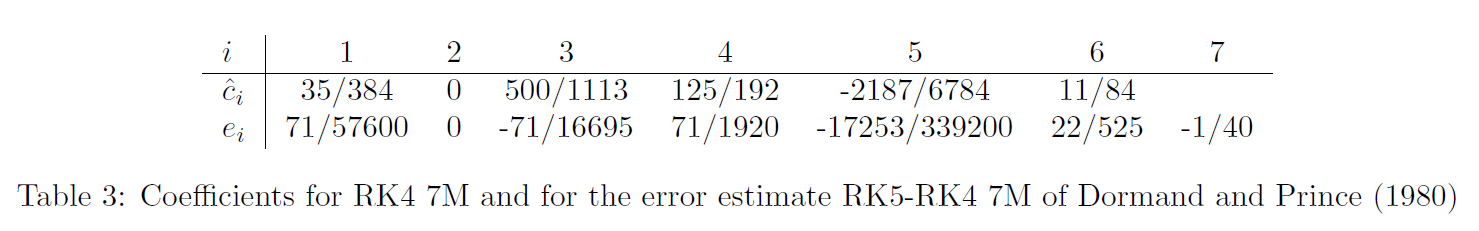

#### 6b) Compute streamlines initiated from $N=10$ seeding points uniformly distributed along the line segment $x=-2,y\in \left\langle 0\ldotp 1,1\ldotp 9\right\rangle$. Use the template `function [strx,stry] = ComputeStreamlines(up,vp,r,th,x0,y0)`.

#### 6c) Plot the streamlines using a solid line with markers. How does the time-step length $\Delta t$ depend on the local velocity and the curvature of the streamlines? Can the computation of streamlines become a stiff problem? How would you avoid the problem from being stiff?

Function 'VecPol2Cart' has already been declared within this scope.

### 7.    Other graphs

#### 7a) Plot the distribution of pressure along the cylinder surface

#### 7b) Plot the velocity profile along the line segment $x=0,y\in \left\langle 0\ldotp 5,3\right\rangle$x = 0; y 2 h0:5; 3i